clc
clear all
addpath(genpath('C:\Users\lorenzo\Videos\nasa'));
filename='2015.nc';
tp=ncread(filename,'tp');

t=double(ncread(filename,'time'));
tt=datevec(t);
fec_ref=datenum('1900-01-01 00:00:00'); %fecha de referencia
t1=(t./24)+fec_ref;
fecha=datevec(t1);
%%PARA LA ACTUALIDAD ES UNA MATRIZ 4D POR ELLO SE USA ESTA LINEA PRINCIPAL
%  a=squeeze(tp(:,:,1,:));
%  x2=squeeze(tp(:,:,2,:));
%  x2(isnan(x2))=0;
%  x=a+x2;
 %PARA AÑOS ANTERIORES UTILIZAR SOLO tp
tp(isnan(tp))=0;
x=tp;

%EL SIGUIENTE PASO ES PARA DEFINIR EL LIMITE TEMPORAL EN EL QUE SE VA A
%PROMEDIAR LAS CORRIENTES

lat=flipud(ncread(filename,'latitude'));
long=ncread(filename,'longitude');
lon=flipud(transpose(long));

[X,Y] = meshgrid(lon,lat);
  
kl=0;
for i=1:2
for j=1:12
    fr=2014+i;
kl=kl+1;
    er=find(fecha(:,1) == fr & fecha(:,2) == j );
    u(:,:,kl)=(mean(x(:,:,er),3,'omitnan'));    
end

for i=1:12
n(:,:,i)=flipud(transpose(u(:,:,i)))*1000;

end
end

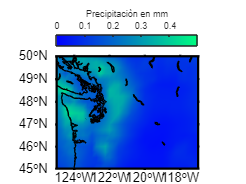

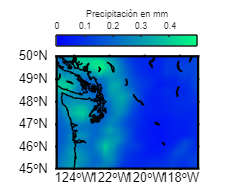

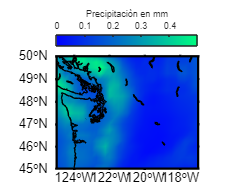

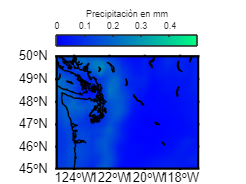

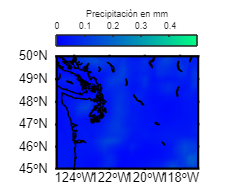

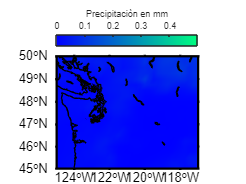

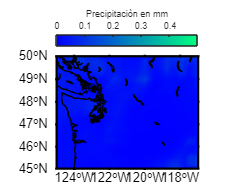

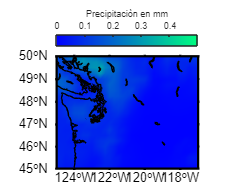

for i=1:12    
figure
%sistema de coordenadas
m_proj('miller','lat',[45 50],'lon',[-125 -117]);
colormap('winter');
m_pcolor(X,Y,n(:,:,i));
shading interp
   m_gshhs_i('color','k');
%m_gshhs_f('patch', [.66 .66 .66]);
%m_gshhs_f('patch',[.7 .7 .7],'edgecolor','none');
c=colorbar('northoutside');
% velocidades
hold on;
%flechas negras
% m_quiver(X,Y,n(:,:,i),g(:,:,i),'k');
% xlabel('nombre grafica');
hold on;
%maya del mapa 
m_grid('linewi',2,'linest','none','tickdir','out','fontsize',12)%'box','fancy')%,'linestyle','-.','gridcolor','k');
c.Label.String = 'Precipitaciòn en mm';
caxis([0 0.5]);
end

% for l=1:8;
%     gh=l;
% subplot(3,3,l)
% %sistema de coordenadas
% m_proj('miller','lat',[2 4],'lon',[-79 -77]);
% colormap(flipud(m_colmap('green',256)));
% m_pcolor(X,Y,ma(:,:,gh));
% shading interp
%  % m_gshhs_i('color','k');
% m_gshhs_f('patch', [.66 .66 .66]);
% %m_gshhs_f('patch',[.7 .7 .7],'edgecolor','none');
% c=colorbar('northoutside');
% % velocidades
% hold on;
% %flechas negras
% m_quiver(X,Y,n(:,:,gh),g(:,:,gh),'k');
% %linea de costa negra
% % xlabel('Corriente superficial departamento de Córdoba');
% hold on;
% %maya del mapa
% % m_grid('box','fancy','tickdir','in');
% %color de grafico
% %
% %color de mapa 
% m_grid('linewi',2,'linest','none','tickdir','out','fontsize',12)%'box','fancy')%,'linestyle','-.','gridcolor','k');
% c.Label.String = 'm/s';
% caxis([0 7]);
% end
